## 2IMN25 (2020-GS2) Assignment 1

# Predictive Maintenance based on Hypothesis Testing

Xuanshu Luo 

1618962

x.luo1@student.tue.nl

## 1. Introduction

In Assembléon, the pick-and-place machines operate several robot arms simultaneously to assemble circuit boards. To ensure expected productivity, maintenance work, such as replacing robot arms that do not meet specifications, had better be scheduled during the idle time of the factory. Therefore, it is essential to predict whether certain robot arms will fail before they really cannot work properly.

To achieve such a prediction, we can compare the performance of a typical robot arm with the observed one. One metric that may be noteworthy is **settling time**, which indicates the time used for a robot arm obtaining the expected speed of movement from a standstill. Under the same conditions, with a given speed, the settling time will change as the friction of the robot arm changes. Hence, a deviation beyond tolerance from the specification settling time represents a strong possibility that the corresponding robot arm should be replaced.

According to the lead mechanical engineer, at the highest speed allowed, the settling time follows a normal distribution with an average of 1.7*ms*, and the maximum standard deviation allowed is 0.5*ms*. A set of measurements of settling time of several robot arms is also provided in *AssignmentPredictiveMaintenance.mat*. Using these data and a given minimum confidence level of 99%, based on hypothesis testing on the average, the maximum variance, and the shape of the distribution of the settling time, this report will give a prediction of which robot arms need maintenance.

In particular, in the second chapter, we introduce hypothesis testing and related methods used in the following chapters. In Chapter 3, we focus on analyzing the sampled data and give predictions based on hypothesis testing. In the last chapter, we will summarize the conclusion we obtained.

% Now, we have:

clear  % clean workspace

% please put the data file and this script in the same directory. 
% Or you can change the directory in the next line.
raw_robot_data = load('./AssignmentPredictiveMaintenance.mat');
robot_arms = raw_robot_data.RobotArms;

expected_mean = 1.7;
expected_std = 0.5;

confindence_level = 0.99;

## 2. Preliminaries

In this chapter, hypothesis test and several methods based on it will be introduced briefly.

### 2.1 Data overview and filtering

The file contains measurements of 28 robot arms. The settling time is given combined with a speed in each element. Since the average settling time and maximum standard deviation are given in regard to highest speed allowed, it is essential to filter the data to delete settling times that are not respect to the maximum speed. We can obtain the maximum speed is 4.2 by traversing the whole dataset. We should also delete the wrong data where the settling time are negative. After filtering, the remaining numbers of data of each robot arms are still sufficiently large (around 1000). The filtered data will be used to perform tests later.

% the number of robot arms
arms_num = size(robot_arms, 2);
disp(['The number of robot arms is ' num2str(arms_num) '.']);
% find the max speed
max_speed = 0;
for i = 1:arms_num
    temp_max = max(robot_arms(i).speed);
    if temp_max > max_speed
        max_speed = temp_max;
    end
end
disp(['The max speed of robot arms is ' num2str(max_speed) '.']);
% filter the data
filtered_data = cell(1, arms_num);
for i = 1:arms_num
    index_concerned = find(robot_arms(i).speed == max_speed);
    time_concerned = robot_arms(i).settling_time(index_concerned);
    time_concerned = time_concerned(time_concerned>0);
    filtered_data{i} = time_concerned;
    
    output = sprintf('The number of data of robot arm %d is %d.', i, size(time_concerned, 1));
    disp(output);
end

### 2.2 Hypothesis testing

A hypothesis test is a systematic way to test whether a claim (or hypothesis) with respect to a population is likely to be true or not [1]. There are two kinds of hypothesis we can make:

- Null hypothesis ($H_0$):  a statement about a population parameter, that is assumed to be true.

- Alternative hypothesis ($H_1$): a statement that contradicts the null hypothesis.

Generally, null hypothesis is a statement that we want to prove to be false. Since we cannot prove a statement but can refute it by examples, we need to make the hypothesis indicating that certain parameters of the sample data are as expected, and we try to disprove it. If we can achieve this in some tests in our report, then it is of a high possibility that corresponding robot arms need maintenance. However, it always possible that we make a wrong prediction. Table 1 shows that there are four outcomes in total when we make a decision on the null hypothesis

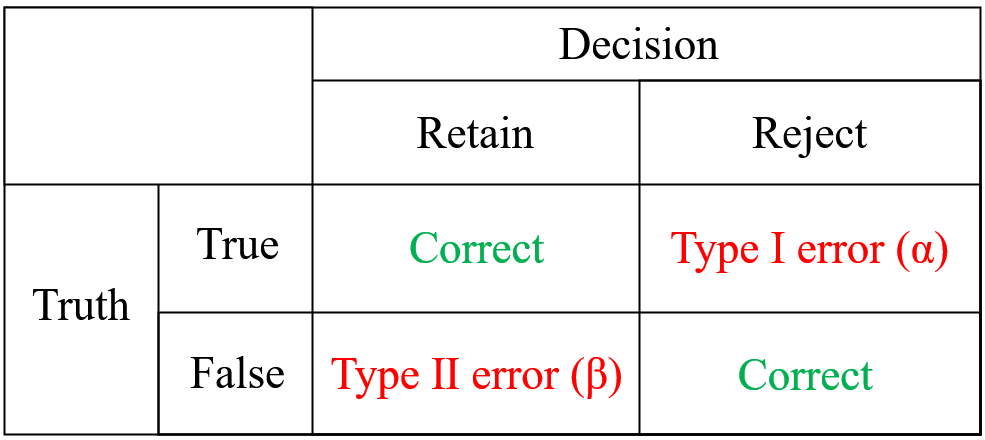

**Table 1** Four outcomes of a decision on the null hypothesis.

where Type Ⅰ error means the decision to reject the null hypothesis which is actually true, and Type ⅠI error means the decision to retain the null hypothesis which is actually false. The probability of Type Ⅰ error is called *level of significance* denoted by $\alpha$, and directly controlled by the confidence level. Concretely, $\alpha =1-\textrm{confidence}\;\textrm{level}$. 

A typical procedure of hypothesis testing is as follows [1]:

- State the hypothesis: give the null hypothesis and alternative hypothesis;

- Set the criteria for a decision: in our report, the confidence level is 99%, that is to say, $\alpha =1-0\ldotp 99=0\ldotp 01$.

- Compute the test statistic;

- Make a decision. We may make mistakes here, and the probability of Type I error is controlled by the confidence level in step 2.

In the following chapters, we will perform the hypothesis testing according to this procedure.

% Now, we have

alpha = 1 - confindence_level;

### 2.3 Methods to evaluate the test statistic

In this section, we will introduce three methods to evaluate the average, the maximum variance and the distribution of the sampled data, respecitively. In these three tests, some values are commonly used. Suppose that $X_1 ,X_2 ,\ldotp \ldotp \ldotp ,X_n$ are independent and identically distributed (IID) random variables with finite population mean $\mu$ and finite population variance $\sigma^2$, then

- *sample mean *is defined as: $\bar{X} \left(n\right)=\frac{\sum_{i=1}^n X_i }{n}$

- *sample variance* is defined as: $S^2 \left(n\right)=\frac{\sum_{i=1}^n {\left\lbrack X_i -\bar{X} \left(n\right)\right\rbrack }^2 }{n-1}$

#### 2.3.1 Test for mean by confidence interval

We can calculate the confidence interval to test the null hypothesis that the sample mean is equal to the expected mean. If the sample size $N$ is sufficiently large, an approximate$1-\alpha$ confidence interval for expected mean $\mu$ is given by [2]:


$$\bar{X_N } \pm z_{1-\frac{1}{2}\alpha } \sqrt{\frac{S^2 \left(N\right)}{N}}$$


That is to say, if


$$\mu \in \left(\bar{X_N } +z_{\frac{1}{2}\alpha } \sqrt{\frac{S^2 \left(N\right)}{N}},\bar{X_N } +z_{1-\frac{1}{2}\alpha } \sqrt{\frac{S^2 \left(N\right)}{N}}\right)$$


then we cannot reject the null hypothesis that sample mean is equal to expected mean. Otherwise, we can reject the null hypothesis, since the statement that the sample mean is equal to expected mean is of a very small possibility to hold.

#### 2.3.2 Test for variance by Chi-square distribution

A chi-square test can be used to test whether the variance of a population is equal to a specified value [3]. Since there is no minimum constraint on the standard deviation, in this report, one-sided test is sufficient. If the sample size $N$ is sufficiently large, then for a confidence level of $1-\alpha$ and expected variance $\sigma^2$, if we have


$$Z_N =\frac{\left(N-1\right)\cdot S^2 \left(N\right)}{\sigma^2 }=\sum_{i=1}^N \frac{{\left(X_i -\bar{X_N } \right)}^2 }{\sigma^2 }<\chi_{1-\alpha ,N-1}^2$$


then we cannot reject the null hypothesis that sample variance is equal to expected variance. Otherwise, we can reject the null hypothesis, since the statement that sample variance is less than expected variance is of a very small possibility to hold.

#### 2.3.3 Test for distribution by Good of Fit testing

It is insufficient to just perform tests on mean and variance. We should also pay attention to the distribution of the sampled data, because the average and the maximum variance cannot restrict a distribution to be the desired shape. In this report, Chi-Square Goodness-of-Fit test [3] will be utilized to test whether a sample of settling time will follow the specified distribution. First, the data will be devided into $k$ *bins*, and for each bin. For $1\le i\le k$, we use $O_i$ to denote the observed frequency and $E_i$ to represent the expected frequency for bin $i$. Given the significant level $\alpha$, if we have


$$T_{\chi } =\sum_{i=1}^k \frac{{\left(O_i -E_i \right)}^2 }{E_i }>\chi_{1-\alpha ,\;k-c}^2$$


where $c$ is the number of estimated parameters for the distribution plus 1, and $k-c$ is the degrees of freedom, then we can reject the null hypothesis that the sample data follows the specific distribution. In our report, our expected distribution is a normal distribution with an average of 1.7*ms* and a maximum standard deviation of 0.5*ms, *so $c=2+1=3$.

% Now, we have

c = 3;

In this chapter, we have introduce the defination of hypothesis testing and how to perform it. The methods used during our following tests are also explained briefly. In the next chapter, these techniques will be utilized to perform tests and give reasonable predictions.

## 3. Analysis and Predictions

In this chapter, we will use hypothesis testing to analyze the sampled data and give predictions. Within every test in the following three sections, steps described in section 2.2 will be performed. At the end of each test, the MATLAB code are listed. All the results are tested in MATLAB R2020b on a desktop running Windows 10 20H2.

### 3.1 Test for mean

In this section, we utilize the technique in section 2.3.1 to calculate the confidence interval and check whether expected mean value (1.7*ms*) is in the interval to decide to reject the null hypothesis or not. Since we need to perform 28 tests, and their overall forms are similar, we will use $i\;\left(1\le i\le 28\right)$ to denote every robot arm. Now, we give the hypothesis testing as follows:

**State the hypothesis**: 

- $H_0$: The average settling time of robot arm $i$ is equal to 1.7*ms.*

- $H_1$: The average settling time of robot arm $i$ is not equal to 1.7*ms.*

**Set the criteria for a decision:**

- The level of significance is 0.01.

**Compute the test statistic:**

- Use the formula in section 2.3.1 to calculate the confidence intervals for every robot arm $i$. Note that $N$ in the formula is the size of filtered data of every robot arms.

**Make a decision**:

- Check whether expected mean 1.7*ms *is within the confidence interval. The result is shown table 2. We can also intuitively obtain the results from Figure 1. According to the results, when $i=4,7,19,24,26,28$, expected mean value is not in their confidence interval, then we can reject the null hypothese for these robot arms that their average of sampled settling time are equal to 1.7*ms.*

- That is to say, we can conclude that robot arm 4, 7, 19, 24, 26, 28 need maintenance with a confidence level of 99%.

- Concretely, since for robot arm 19 and 28, the expected mean is less than the lower bound, we can further conclude that arm 19 and arm 28 is overdamped. Similarly, we can conclude that robot arm 4, 7, 24, 26 is underdamped.

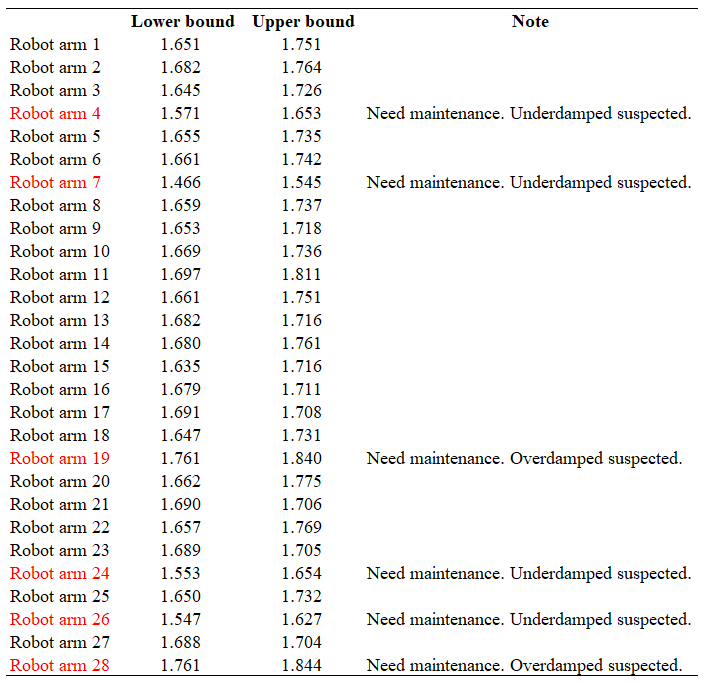

**Table 2** Confidence intervals for 99% confidence level and expected mean value of 28 robot arms

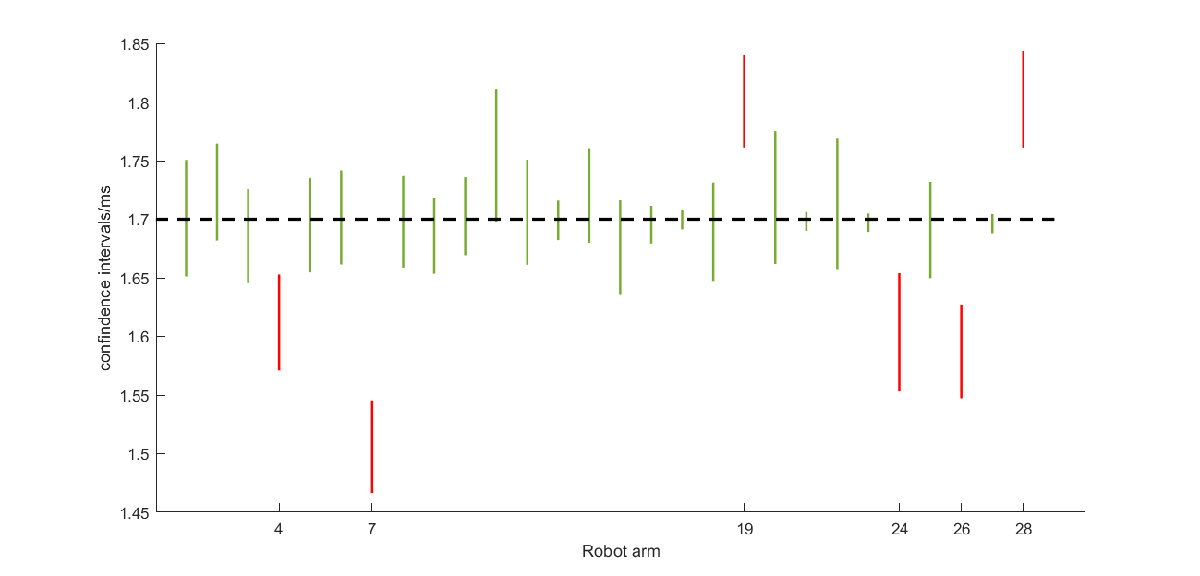

**Figure 1** Confidence intervals for 99% confidence level and expected mean value of 28 robot arms

pd = makedist('Normal', 'mu', 0, 'sigma', 1);
z_alpha_l = icdf(pd, alpha/2);
z_alpha_r = icdf(pd, 1-alpha/2);

arms_need_replace = [];
for i = 1:arms_num
    time_concerned = filtered_data{i};
    N = size(time_concerned, 1); % the number of experiments
    sample_mean = sum(time_concerned) / N;
    sample_var = sum((time_concerned - sample_mean).^2)/(N-1);
    
    confindence_interval_l = sample_mean + z_alpha_l*sqrt(sample_var/N);
    confindence_interval_r = sample_mean + z_alpha_r*sqrt(sample_var/N);
    
    
    output = sprintf('The confidence interval of arm %d is [%.3f, %.3f].', i, confindence_interval_l, confindence_interval_r);
    result = '';
    if confindence_interval_l > expected_mean || expected_mean > confindence_interval_r
        result = ' Need maintenance.';
        arms_need_replace = [arms_need_replace i];
    end
    disp([output result]);
    
    
    line([0 arms_num+1], [expected_mean expected_mean], 'Color','k', 'LineWidth', 2, 'linestyle', '--');
    if confindence_interval_l < expected_mean && expected_mean < confindence_interval_r
        line([i i], [confindence_interval_l confindence_interval_r], 'Color','#77AC30', 'LineWidth', 1.5);
    else
        line([i i], [confindence_interval_l confindence_interval_r], 'Color','r', 'LineWidth', 1.5);
    end
    xticks(arms_need_replace);
end

### 3.2 Test for variance

In this section, we utilize the technique in section 2.3.2 to check whether the standard deviation of sampled data of every robot arm is larger than the expected maximum value (0.5*ms*) to decide to reject the null hypothesis or not. Similarly, we will use $i\;\left(1\le i\le 28\right)$ to denote every robot arm. Now, we give the hypothesis testing as follows:

**State the hypothesis**: 

- $H_0$: The standard deviation of settling time of robot arm $i$ is no more than 0.5*ms.*

- $H_1$: The standard deviation of settling time of robot arm $i$ is greater than 0.5*ms.*

**Set the criteria for a decision:**

- The level of significance is 0.01.

**Compute the test statistic:**

- Use the formula in section 2.3.2 to calculate $Z_N$ for every robot arm $i$. Note that $N$ in the formula is the size of filtered data of every robot arms.

**Make a decision**:

- Check whether the formula holds. The result is shown in Table 3. According to the results, when $i=1,11,12,20,22,24$, $Z_N >\chi_{1-\alpha ,N-1}^2$, then we can reject the null hypothese for these robot arms that their standard deviation of settling time are no more than 0.5*ms.*

- That is to say, we can conclude that robot arm 1, 11, 12, 20, 22, 24 need maintenance with a confidence level of 99% due to their operation time are not highly predictable.

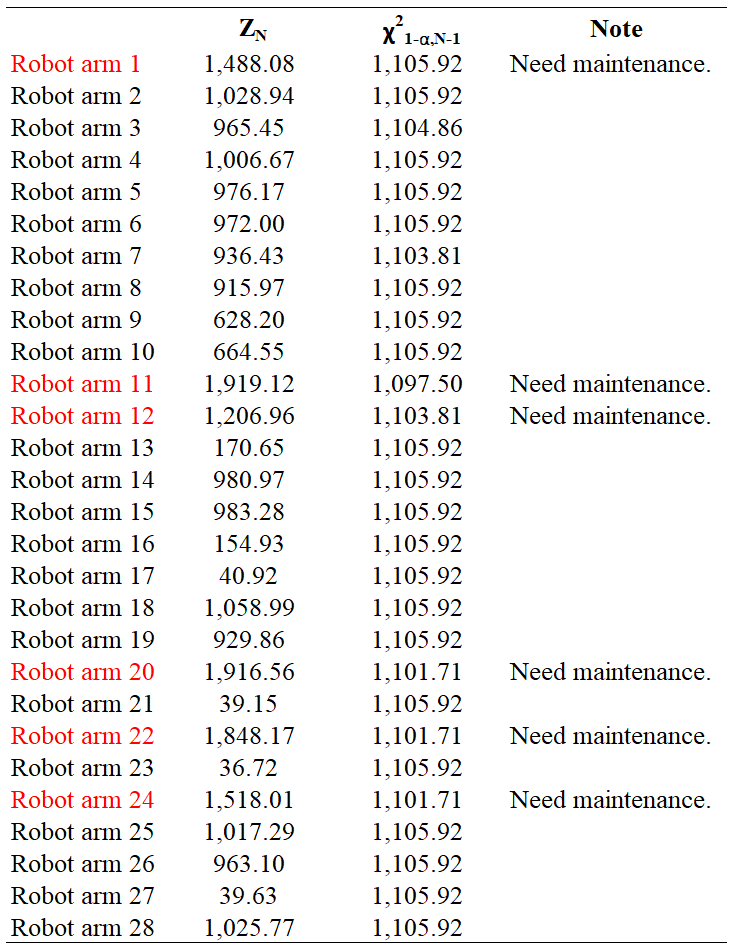

**Table 3** Test results for variance for a confidence level of 99% for 28 robot arms

for i = 1:arms_num
    time_concerned = filtered_data{i};
    N = size(time_concerned, 1); % the number of experiments
    sample_mean = sum(time_concerned) / N;
    sample_var = sum((time_concerned - sample_mean).^2)/(N-1);
    
    z_n = sum((time_concerned - sample_mean).^2/(expected_std^2));
    
    result = z_n <= icdf('Chisquare', 1-alpha, N-1);
    
    if result
        output = sprintf('The standard deviation of arm %d is less than 0.5ms', i);
    else
        output = sprintf('The standard deviation of arm %d is greater than 0.5ms for a confidence level of 99%%. Need maintenance.', i);
    end
    disp(output);
end

### 3.3 Test for distribution

In this section, we utilize the technique in section 2.3.3 to check whether the sampled data comes from a normal distribution with a mean and variance estimated from it to decide to reject the null hypothesis or not. Here we use the sample mean and sample variance other than the expected ones, since we just want to check whether the data is sampled from a normal distribution or not. If we use expected mean and variance, the hypothesis will change to *the sampled data of robot arm *$i$* comes from a normal distribution with expected mean and variance. *Due to the fact that we only know that 0.5*ms *the maximum value allowed, the hypothesis respected to the data sampled from a lower variance will also be rejected, which is actually wrong. 

Similarly, we will use $i\;\left(1\le i\le 28\right)$ to denote every robot arm. Now, we give the hypothesis testing as follows:

**State the hypothesis**: 

- $H_0$: The sampled data of robot arm $i$ comes from a normal distribution with a mean and variance estimated from the sampled data*.*

- $H_1$: The sampled data of robot arm $i$ does not come from a normal distribution with a mean and variance estimated from the sampled data*.*

**Set the criteria for a decision:**

- The level of significance is 0.01.

**Compute the test statistic:**

- Use the formula in section 2.3.3 to calculate $T_{\chi }$ for every robot arm $i$. Note that $N$ in the formula is the size of filtered data of every robot arms. 

**Make a decision**:

- Check whether the formula holds. The result is shown in Table 4. According to the results, when $i=2,4,14,15,18,20,22,25,28$, $T_{\chi } >\chi_{1-\alpha ,\;k-c}^2$, then we can reject the null hypothese for these robot arms that the sampled data of robot arm $i$ comes from a normal distribution*.*

- We can also use q-q plot to see the results intuitively [4]. If the distribution of sampled data is normal, then the data plot appears linear. For example, as shown in Figure 2, we can see that the data plot of robot arm 5 is approximately linear, and we indeed cannot reject the null hypothesis of this arm. In contrast,  the data plot of robot arm 14 is far away from linear, and the fact is the null hypothesis of robot arm 14 is rejected. Figures for other robot arms can be generated by the MATLAB code below.

- We can conclude that robot arm 2, 4, 14, 15, 18, 20, 22, 25, 28 need maintenance with a confidence level of 99% due to their settling time do not fit in normal distribution as required.

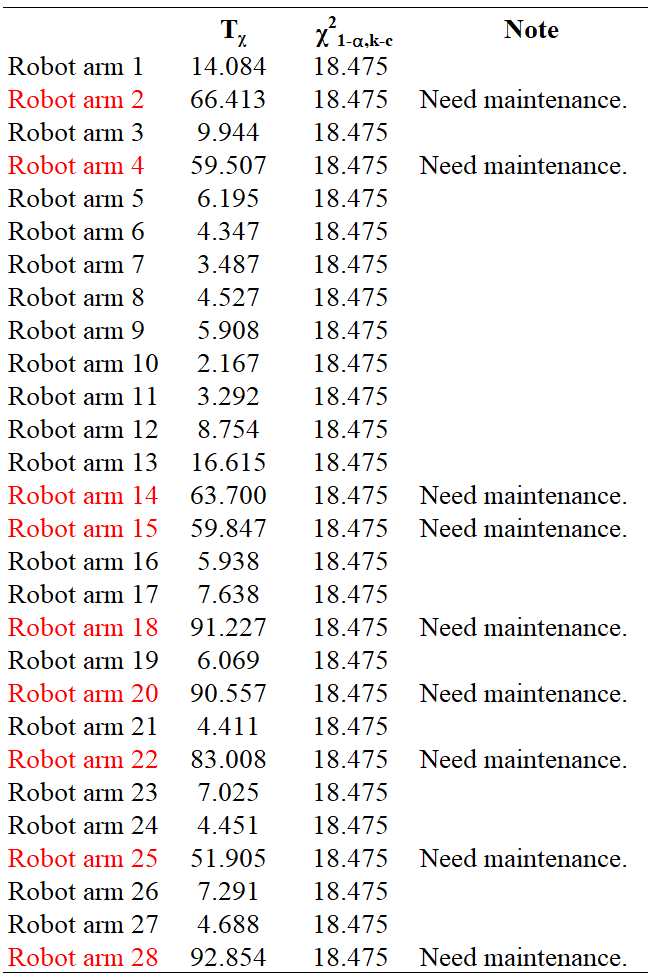

**Table 4** Test results for distribution for a confidence level of 99% of 28 robot arms

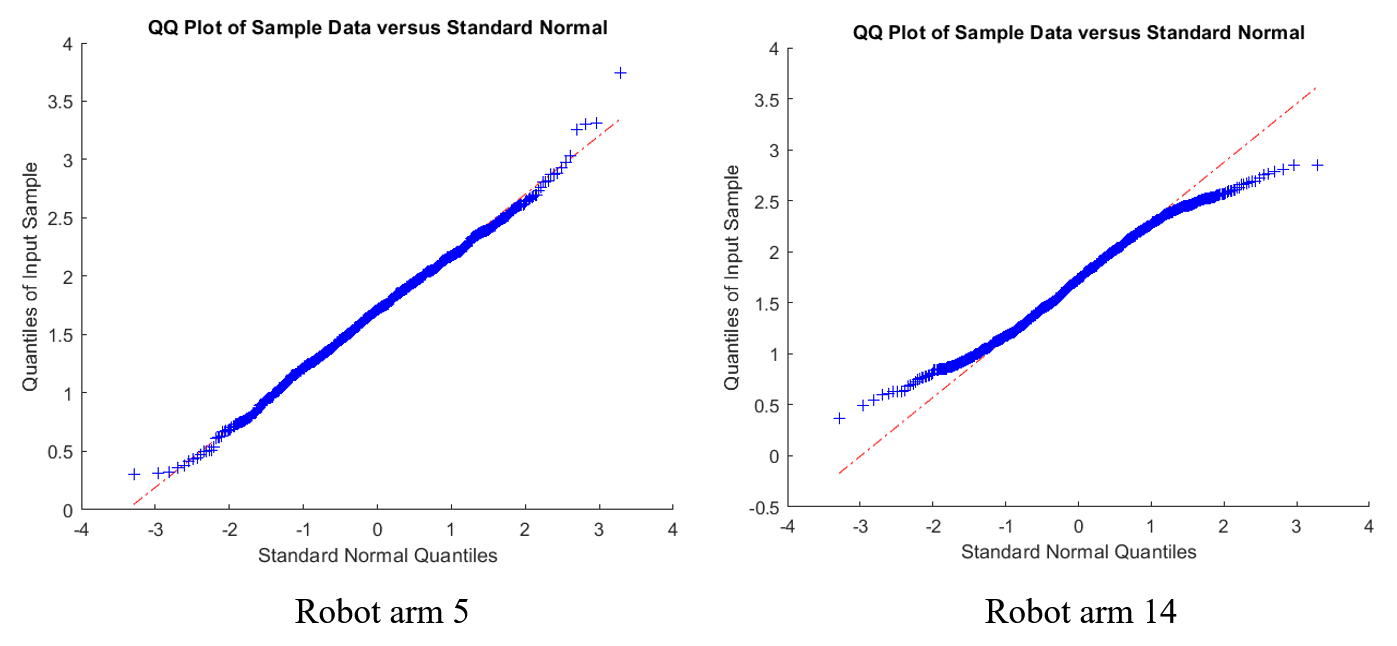

**Figure 2** Test results comparison for distribution for a confidence level of 99% of robot arm 5 and 14

bin_num = 10;
for i = 1:arms_num
    time_concerned = filtered_data{i};
    N = size(time_concerned, 1); % the number of experiments
    
    sample_mean = sum(time_concerned) / N;
    sample_std = sqrt(sum((time_concerned - sample_mean).^2)/(N-1));
    
    flag = true;
    while flag
        df = bin_num - c;
        bin_edge = linspace(min(time_concerned), max(time_concerned), bin_num+1);
        o_i = zeros(1, bin_num);
        for j = 1:bin_num
            if j ~= bin_num
                o_i(j) = length(time_concerned(time_concerned>=bin_edge(j) & time_concerned<bin_edge(j+1)));
            else
                % add the max sample
                o_i(j) = length(time_concerned(time_concerned>=bin_edge(j) & time_concerned<=bin_edge(j+1)));
            end
        end
        if min(o_i == 0)
            % if there is a bin that has no samples, decrease the number of bins,
            % and perform again, do not change flag, keep looping
            bin_num = bin_num-1;
        else
            % every bin has samples, change flag, end loop
            flag = false;
        end
    end
    
    temp = cdf('normal', bin_edge(2:(length(bin_edge)-1)), sample_mean, sample_std);
    e_i = N * diff([0 temp 1]);
    
    result = sum(((o_i - e_i).^2)./e_i) < icdf('Chisquare', 1-alpha, df);
    
    if result
        output = sprintf('Sampled data of arm %d is from a normal distribution.', i);
    else
        output = sprintf('Sampled data of arm %d is not from a normal distribution for a confidence level of 99%%.', i);
    end
    disp(output);
    
    figure
    qqplot(time_concerned);
end

## 4. Conclusion

Based on hypothesis testing, we utilize several method to analyze and give convincing prediction for a confidence level of 99%. Finally, we can summarize the results and give a final conclusion. There are 16 robot arms may need maintenance: robot arm 1, 2, 4, 7, 11, 12, 14, 15, 18, 19, 20, 22, 24, 25, 26 and 28. The concrete issues they may have are shown in Table 5. Note that for some robot arms, there may be more than one issue need to investigate for maintenance personnel.

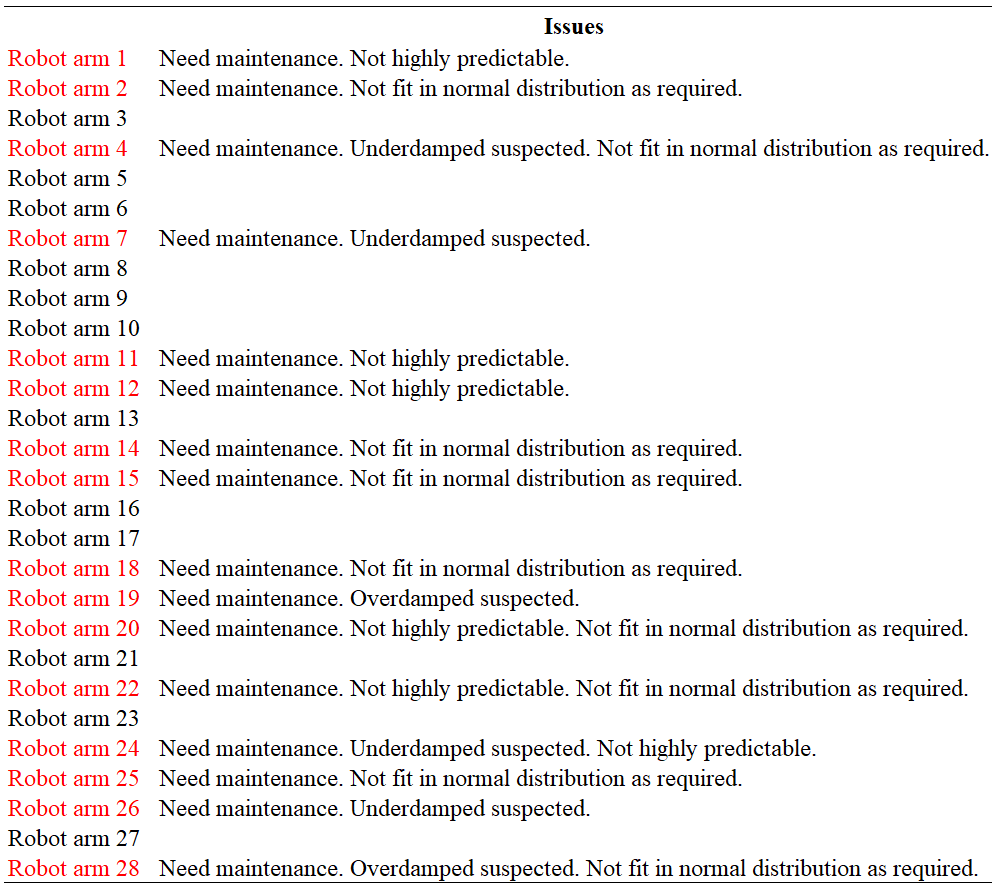

**Table 5** The final prediction of the maintenance and possible issues of 28 robot arms.

## Reflection

In the section 3.2, using the current method, it is difficult to make intuitive figures like Figure 1. I think the test for variance can also be performed by calculating a confidence interval like the test of the mean value. The difference is we only need to focus on the upper bound in this scenario. The following formula may be right, but unfortunately, I do not have enough time to check it.


$$\sigma \le \sqrt{\frac{\left(N-1\right)\cdot S^2 \left(N\right)}{\chi_{\alpha ,\;N-1}^2 }}$$


## Acknowledgement

Thanks for the discussion in the Canvas. There are many thought-provoking questions there, espectially the questions from Yimi Zhao and Gijs Bekkers about the GoF. Also I appreciate the answers given by Professor Pieter Cuijpers that gave me a lot of inspiration.

## Reference

[1] Privitera, G. J. (2011). *Statistics for the behavioral sciences, Chapter 8*. Sage.

[2] Law, A. M., Kelton, W. D., & Kelton, W. D. (2000). *Simulation modeling and analysis* (Vol. 3)*, Chapter 4*. New York: McGraw-Hill.

[3] Snedecor, G. W., & Cochran, W. G. (1989). Statistical Methods, eight edition. *Iowa state University press, Ames, Iowa*.

[4] Gnanadesikan, R., & Wilk, M. B. (1968). Probability plotting methods for the analysis of data. *Biometrika*, *55*(1), 1-17.